close all;clear;clc

# Initialising constants

m=20; l=10; g=9.81;

# Solving the differential equations using ode45

% Initial conditions [theta1; theta2; omega1; omega2]
x0 = [pi/3;pi/2;0;0];
% Time span
ts = 0:0.01:20;

[t,x] = ode45('MCK',ts,x0);

# Energy Equations

V = -(0.25*g*l*m).*(7*cos(x(:,1))+3*cos(x(:,2))-5.*sin(x(:,1))-sin(x(:,2)));
T = ((1/48)*l^2*m).*(73.*x(:,3).^2+24.*(2.*cos(x(:,1)-x(:,2))-sin(x(:,1)-x(:,2))).*x(:,3).*x(:,4)+25.*x(:,4).^2);
Total = V+T; 

# Results

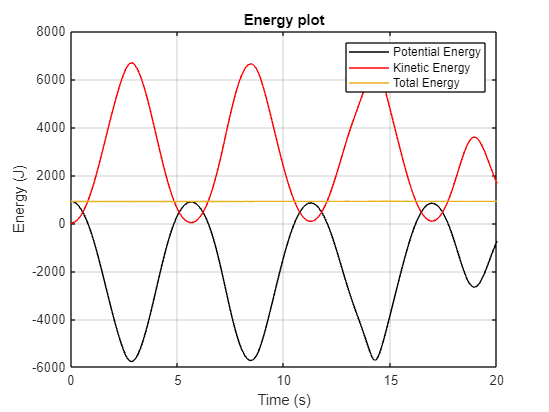

figure('Name','Total Energy')
plot(t,V,'black',t,T,'r',t, Total)
title('Energy plot')
ylabel('Energy (J)')
xlabel('Time (s)')
legend('Potential Energy','Kinetic Energy','Total Energy')
grid on